# Customize a Colormap

The `customcolormap` function is able to define a customized colorbar given the positions and the colors that should generate the final gradients.

The parameters are the following:

- `positions`: Vector of positions, from 0 to 1. The first position (0) and the last position (1) must be always included. Note that the 0 position would be the maximum value, whereas the 1 position must be the minimum value of the colorbar.

- **colors**: Colors that must placed in each position. This parameter can be specified as a RGB matrix, or as a cell vector.

## A custom colormap with 3 colors

In this example, we are going to generate a colormap with 3 equally-spaced colors: white-red-black.

As aforementioned, we can specify them as RGB values (normalized to 1):

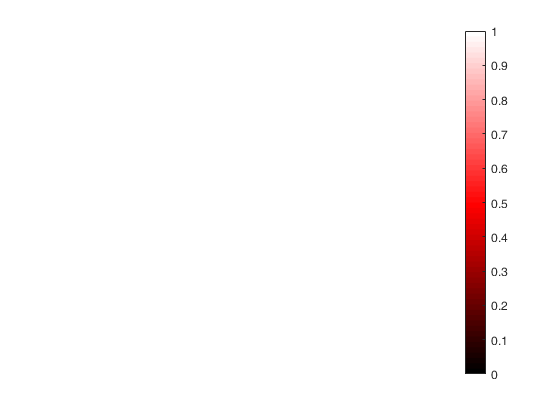

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

colorbar;
colormap(mycolormap);
axis off;

Or as HTML values (in a cell vector):

mycolormap = customcolormap([0 0.5 1], {'#ffffff','#ff0000','#000000'});
colorbar;
colormap(mycolormap);

axis off;

## Creating non equally-spaced colormaps

In this example, we are goind to create a colormap with non equally-spaced positions. For instance, we are going to place: bone at 0%, yellowish orange at 30%, orange at 80%, and purple at 100%.

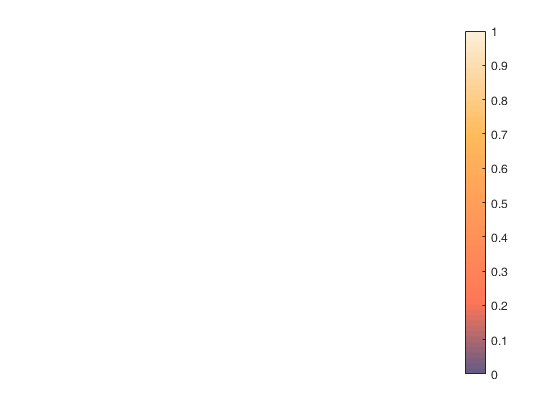

mycolormap = customcolormap([0 .3 .8 1], {'#fbeed7','#ffba5a','#ff7657','#665c84'});
colorbar;
colormap(mycolormap);
axis off;

## Extending the initial or the last color

Since the first (0) and the last (1) positions must be always included, a common question would be how the first or the last colors must be extended. This could be achieved by indicating an extra position and duplicating the color. 

In this example, we are going to extend the white of the first example until the 30% position:

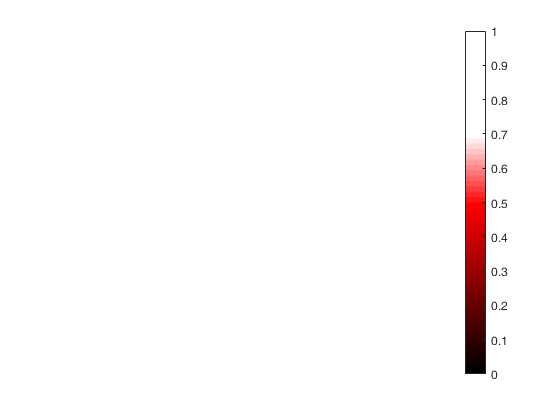

mycolormap = customcolormap([0 .3 .5 1], {'#ffffff','#ffffff','#ff0000','#000000'});
colorbar;
colormap(mycolormap);
axis off;